# Lab - Boundary value problems 1

**Topics: **analytical solution for BVPs, shooting method for linear equations, shooting method for non-linear equations

## Water table height

clear, clc, format compact

Given: $K\bar{h} \;\frac{d^2 h}{{\textrm{dx}}^2 }+N=0$

Solve for the height of the water table for x = 0 to 1000 m where h(0)=10 m and h(1000)=5 m. Use the following parameters: K=1 m/d and N=0.0001 m/d. Use the average of the boundary conditions as the average height ($\bar{h}$).

### Set up variables

k = 1;
n = 0.0001;

x0 = 0;
xf = 1000;

h0 = 10;
hf = 5;
hbar = (h0+hf)/2;

### **Analytical solution**


$$K\bar{h} \;\frac{d^2 h}{{\textrm{dx}}^2 }+N=0$$


syms h(x)
ode = k*hbar*diff(h, x, 2)+n == 0;
cond1 = h(x0) == h0;
cond2 = h(xf) == hf;
conds = [cond1 cond2];
analitical(x) = dsolve(ode, conds)

$$analitical(x) = -\frac{x^{2}}{150000}+\frac{x}{600}+10$$

### System of ODEs


$$\frac{d}{\textrm{dx}}\left\lbrack \begin{array}{c}
h\\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
u\\
-\frac{N}{K\bar{h} }
\end{array}\right\rbrack$$


dh = @(x,H) [H(2); -n/(k*hbar)];

### 1st shot

z1 = 0;
[x1, h1] = ode45(dh, [x0 xf], [h0 z1]);
h1end = h1(end,1)

h1end = 3.3333

### 2nd shot

z2 = 0.001;
[x2, h2] = ode45(dh, [x0 xf], [h0 z2]);
h2end = h2(end,1)

h2end = 4.3333

### Linear interpolation to find dh/dx


$$g_f =g_1 +\frac{g_2 -g_1 }{T_2 -T_1 }\left(T_f -T_1 \right)$$


zactual = z1 + (z2 - z1)/(h2end - h1end)*(hf-h1end)

zactual = 0.0017

### Numerical solution

[x,H] = ode45(dh, [x0 xf], [h0 zactual]);
hf - H(end,1)

ans = -8.8818e-16

### Plot the height

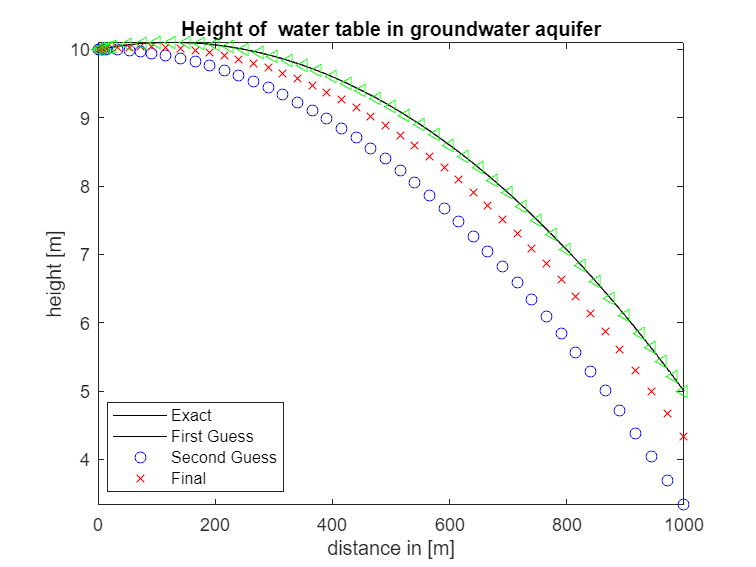

figure(1)
fplot(analitical, [x0 xf], 'k')
hold on
 plot(x1, h1(:,1), 'bo',x2, h2(:,1), 'rx', x, H(:,1),'g<')
hold off
title 'Height of  water table in groundwater aquifer'
xlabel 'distance in [m]'
ylabel 'height [m]'
legend('Exact','First Guess','Second Guess','Final','location','best')

## Better version of water table height

A better equation is $\textrm{Kh}\;\frac{d^2 h}{{\textrm{dx}}^2 }+{K\left(\frac{\textrm{dh}}{\textrm{dx}}\right)}^2 +N=0$.  Solve again for the height of the water table for x = 0 to 1000 m where h(0)=10 m and h(1000)=5 m. Use the following parameters: K=1 m/d and N=0.0001 m/d. 

### Set up variables

clear, clc, format compact
k = 1;
n = 0.0001;

x0 = 0;
xf = 1000;

h0 = 10;
hf = 5;
hbar = (h0+hf)/2;

### **Analytical solution**


$$y\left(x\right)=x^2 +\frac{16}{x}$$


syms h(x)
dH = diff(h);
ode = k*h*diff(h,x,2)+k*dH^2+n == 0;

cond1 = h(x0) == h0;
cond2 = h(xf) == hf;
conds = [cond1 cond2];
analitical(x) = dsolve(ode, conds)

$$analitical(x) = \frac{\sqrt{-x^{2}+250\,x+1000000}}{100}$$

### Find where residual = 0

za = fzero(@shootingRes, 0.005, [], k, n, x0, xf, h0, hf)

za = 0.0013

### Numerical solution

[x,h] = ode45(@dhdxNonlinear, [x0 xf], [h0, za], [], k, n);

### Plot the height

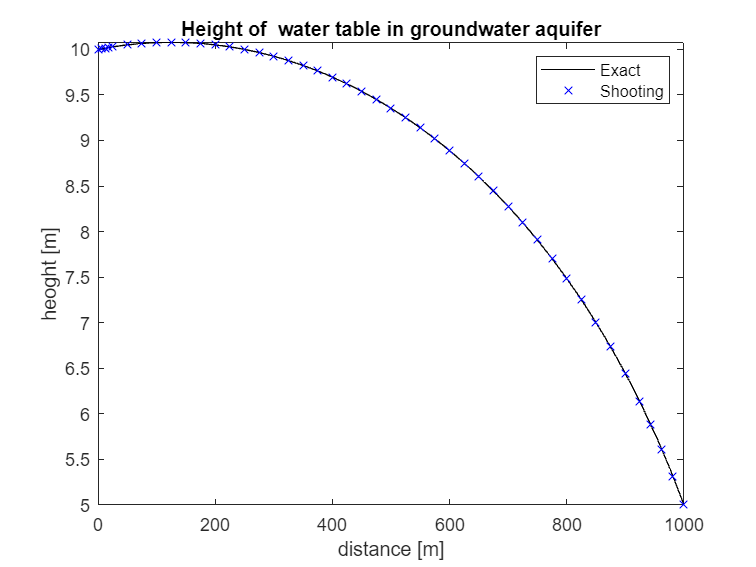

figure(2)
fplot(analitical, [x0 xf], 'k')
hold on
plot(x, h(:,1),'bx')
hold off
title 'Height of  water table in groundwater aquifer'
xlabel 'distance [m]'
ylabel 'heoght [m]'
legend('Exact', 'Shooting')

## Helper functions

### Non-linear system function


$$\frac{d}{\textrm{dx}}\left\lbrack \begin{array}{c}
h\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
z\\
\frac{-{\textrm{Kz}}^2 -N}{\textrm{Kh}}
\end{array}\right\rbrack$$


function dH = dhdxNonlinear(x, H, k, n)

dH = [H(2); (-k*H(2)^2-n)/(k*H(1))];

end

### Residual function

function r = shootingRes(za, k, n, x0, xf, h0, hf)

[~,h] = ode45(@dhdxNonlinear, [x0 xf], [h0, za], [], k, n);
r = h(end,1) - hf;
end